# H3

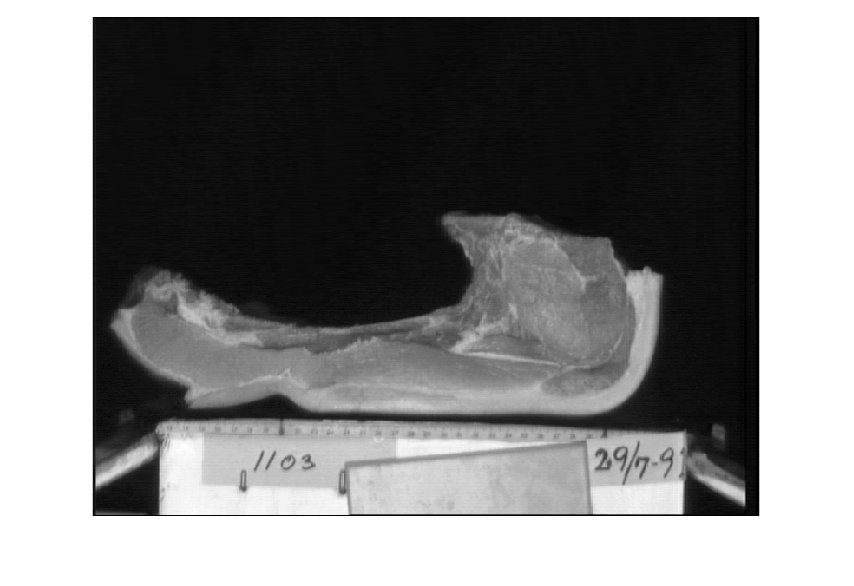

close all
a = dir('/Users/jiabowang/Desktop/VC/images/chuletons/*.bmp');
nf = size(a);

for i = 1:nf 
    filename = horzcat(a(i).folder,'/',a(i).name);
    I = imread(filename);
    imshow(I)
    drawnow
end

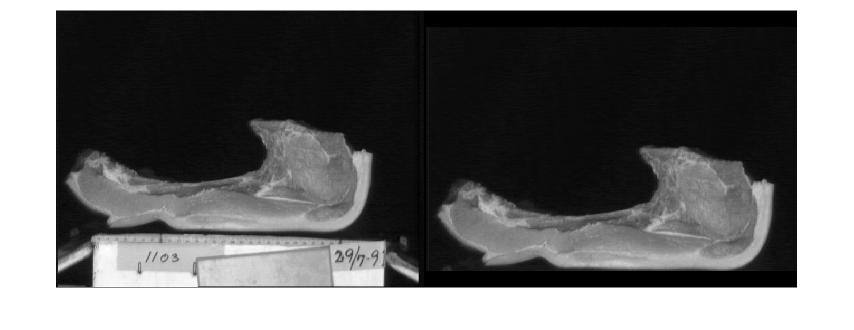

I = imread("F1103flb.bmp");
I2 = imcrop(I,[0 0 700 460]);
montage({I,I2});

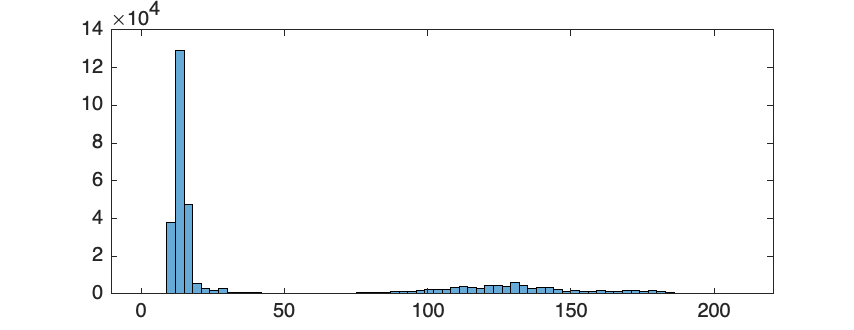


histogram(I2)

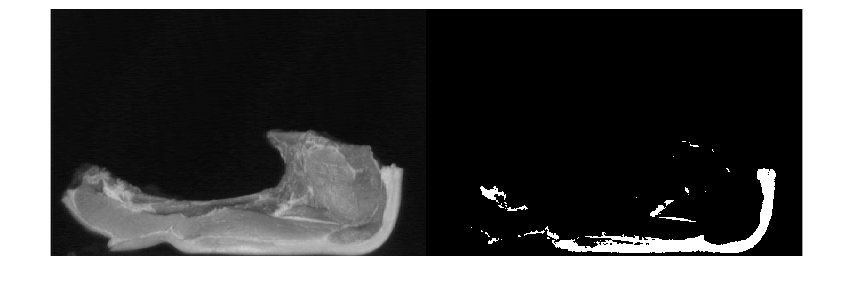

BW1 = I2 > 160;
montage({I2, BW1});

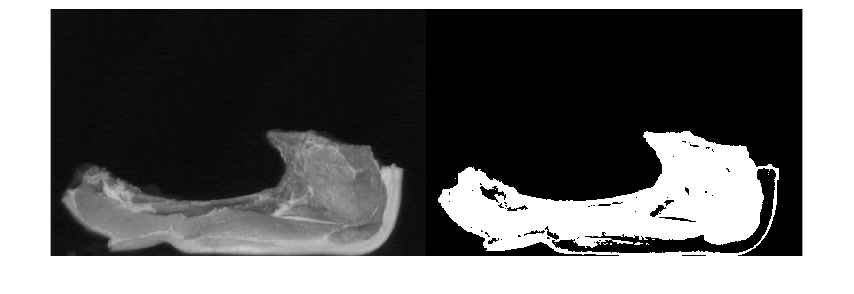


BW2 = I2 > 70 & I2 < 160;
montage({I2, BW2});


%grasa
grasa = sum(BW1) / (sum(BW1) + sum(BW2))

grasa = 0.1492

% F1011 -> 160
% F1019 -> 190
% F1031 -> 200
% F1051 -> 195
% F1053 -> 145
% F1059 -> 160
% F1064 -> 155
% F1079 -> 185
% F1083 -> 175
% F1096 -> 170
% F1097 -> 170
% F1101 -> 170
% F1102 -> 170
% F1103 -> 160

level = graythresh(I2)

level = 0.2784

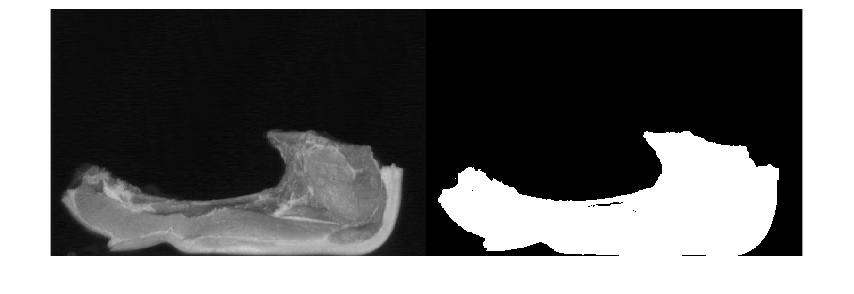

BW3 = imbinarize(I2, level);

level2 = graythresh(uint8(BW3));
BW4 = imbinarize(uint8(BW3), level2);

montage({I2, BW3})

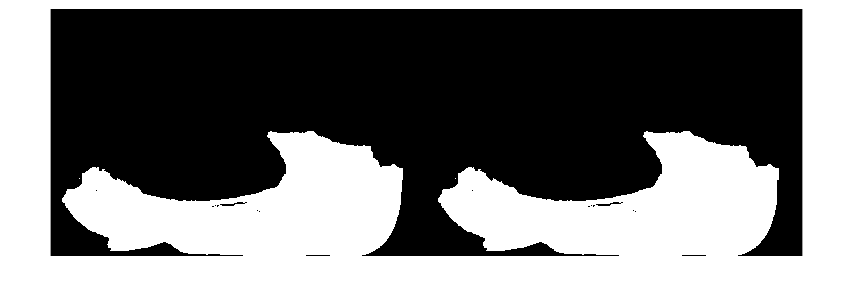


montage({BW3, BW4})

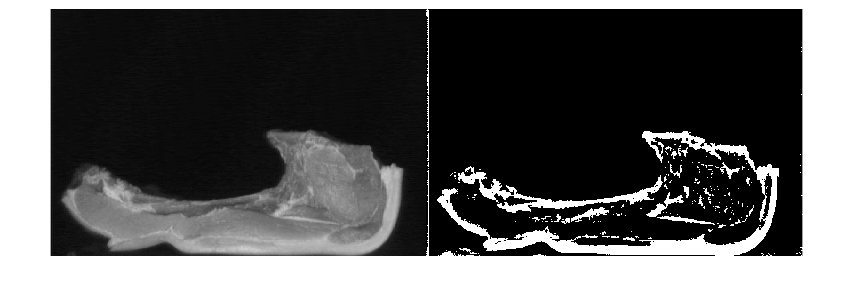

window = [40 20];
M = colfilt(I2, window, 'sliding', @mean); 
k = 10;
BW = I2 > M + k;
%fosc BW = I < M - k;
montage({I2,BW});

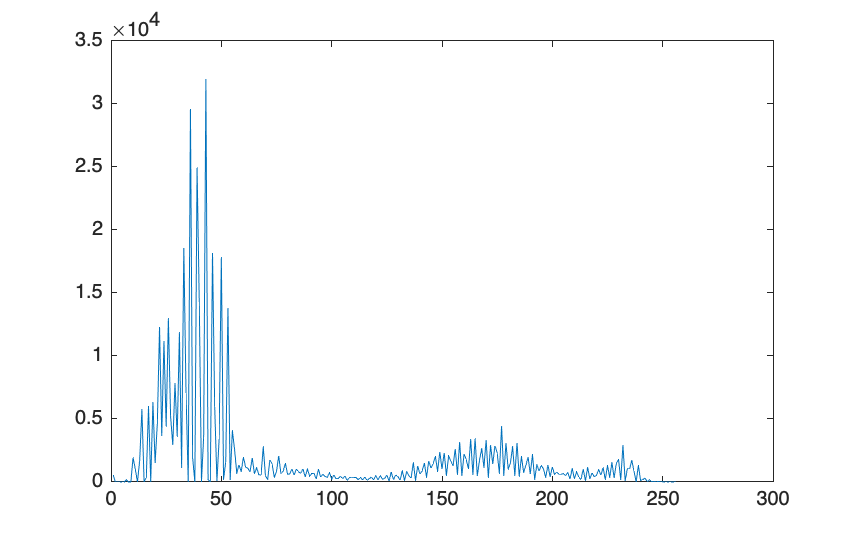

[f, c] = size(I2);
h = imhist(I2);
p = h/f*c;
plot(p)

level = otsu(p)

level = 110

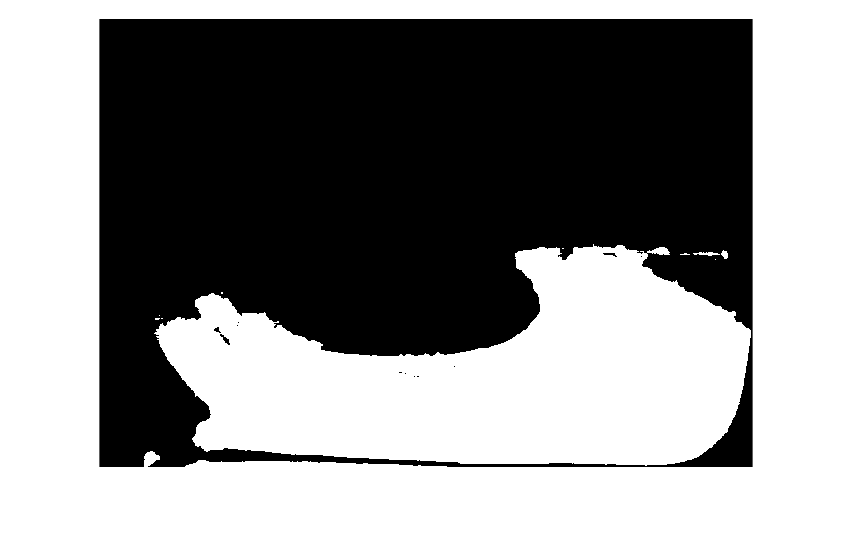

BW = I2 > level;
imshow(BW);

function level = otsu(histogramCounts)
total = sum(histogramCounts); % total number of pixels in the image 
%% OTSU automatic thresholding
top = 256;
sumB = 0;
wB = 0;
maximum = 0.0;
sum1 = dot(0:top-1, histogramCounts);
for ii = 1:top
    wF = total - wB;
    if wB > 5 && wF > 5
        mF = (sum1 - sumB) / wF;
        val = wB * wF * ((sumB / wB) - mF) * ((sumB / wB) - mF);
        if ( val >= maximum )
            level = ii;
            maximum = val;
        end
    end
    wB = wB + histogramCounts(ii);
    sumB = sumB + (ii-1) * histogramCounts(ii);
end
end